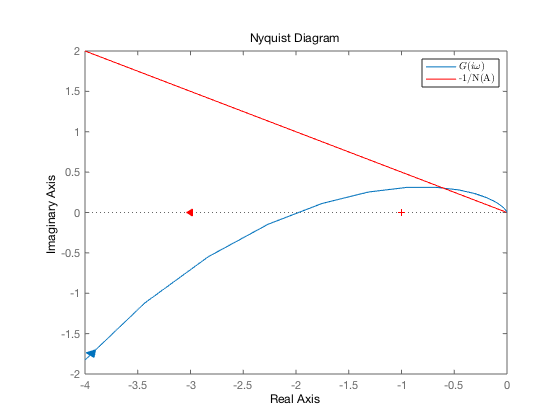

clear variables
A = 0:0.01:10;
a_1 = zeros(size(A));
for k = 1:length(A)
% odd function, a_1=0
a_1(k) = integral(@(phi)(1*sign(A(k)*sin(phi)) ...
    +0.5*sign(A(k)*cos(phi))).*cos(phi),0,2*pi)/pi;
b_1(k) = integral(@(phi)(1*sign(A(k)*sin(phi)) ...
    +0.5*sign(A(k)*cos(phi))).*sin(phi),0,2*pi)/pi;
end
N = (b_1+i*a_1)./A;

s = tf('s');
G = 4/s/(s+1)^2;
h = nyquistplot(G);
set(h,'ShowFullContour','off');
ylim([-2,2])
xlim([-4,0])
hold on
plot(real(-1./N),imag(-1./N),'r',-3,0,'r<','MarkerFaceColor','r')
legend('$G(i\omega)$','-1/N(A)','interpreter','latex')

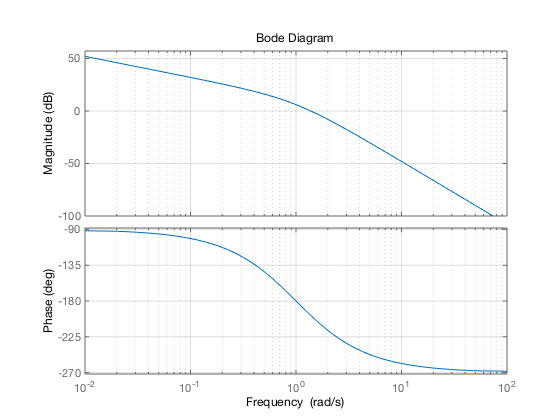

figure();
bode(G);
grid on;

-180-atan(0.5)*180/pi

ans = -206.5651